# Compute Spectrogram

## Matlab Startup File

This m-File code prepare the enviroment to provide access to auxilliary files and sub-folders.

clear; clc; close all;
format short eng                              
[ProjectFolder,AuxFcn_GS] = AuxFcn_Matlab_Startup_File_001; % Project Startup Folder & Graphical Settings

## Import Signal Data

#### Signal Preprocessing

Pressure reading corrected (offset/baseline removed)

load('E2038.mat'); 

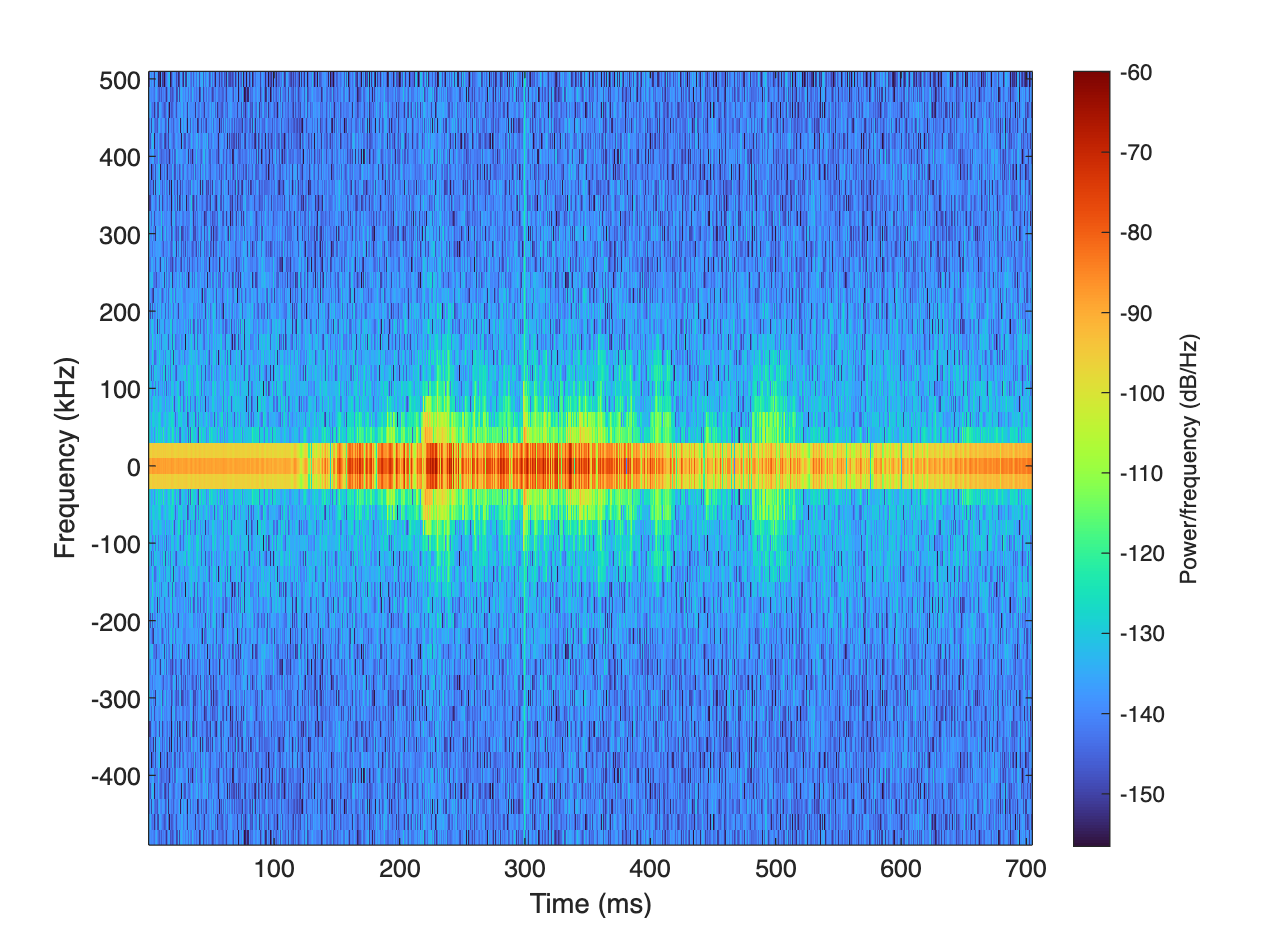

dataPoffsetCorrected = p - mean(p(1:100,:), 1);
Fs = fs;             % Sampling frequency in Hz
t = (0:length(dataPoffsetCorrected)-1)'/Fs;

% Parameters
timeLimits = [min(t) max(t)]; % seconds
frequencyLimits = [2495.589 32958.99]; % Hz
overlapPercent = 50;

%%
% Index into signal time region of interest
pz_6_ROI = pz(:,6);
sampleRate = 1000000; % Hz
startTime = 0; % seconds
timeValues = startTime + (0:length(pz_6_ROI)-1).'/sampleRate;
minIdx = timeValues >= timeLimits(1);
maxIdx = timeValues <= timeLimits(2);
pz_6_ROI = pz_6_ROI(minIdx&maxIdx);
timeValues = timeValues(minIdx&maxIdx);

% Compute spectral estimate
% Run the function call below without output arguments to plot the results
% [P,F,T] = pspectrum(pz_6_ROI,timeValues, ...
%     'spectrogram', ...
%     'FrequencyLimits',frequencyLimits, ...
%     'OverlapPercent',overlapPercent);
spectrogram(dataPoffsetCorrected(:,6)-mean(dataPoffsetCorrected(:,6)),50,25,50,Fs,'centered','yaxis')
colormap turbo